Limpar 

close all
clear
clc

# Analise CC para emisro comum com polarização por divisor de tensão

## ESTAGIO 1:

Figura 1- Circuito base

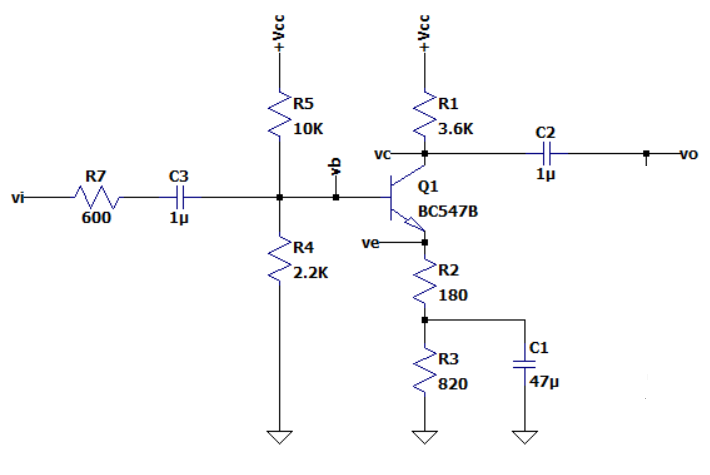

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

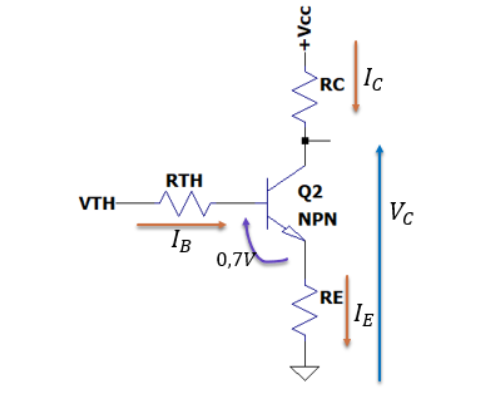

### Valores dos componentes:

R1E1 = 33e+3;%%Rth
R2E1 =2.2e+3;%%Rth
ReE1E1 = 10;
R3E1 = 190;
REE1 = ReE1E1+R3E1;%% R2+R3
VccE1 = 18;%%Variavel de entrada
BE1 = 290; % Beta para o calc
VbeE1 = 0.7; 
VceE1 = 5; %data sheet


### Equivalentes de TH

VthE1 = (R2E1/(R1E1+R2E1))*VccE1

VthE1 = 1.1250

RthE1 = ((1/R1E1)+(1/R2E1))^-1

RthE1 = 2.0625e+03

### Correntes

IbE1 = (VthE1-VbeE1)/(RthE1+REE1*(BE1+1))

IbE1 = 7.0525e-06

IcE1 = (BE1+1)*IbE1

IcE1 = 0.0021

IeE1 = IcE1

IeE1 = 0.0021

### Tensões CC

VbE1 = VthE1

VbE1 = 1.1250

VeE1 = REE1*IeE1

VeE1 = 0.4105

VcE1 = VceE1+VeE1

VcE1 = 5.4105

## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

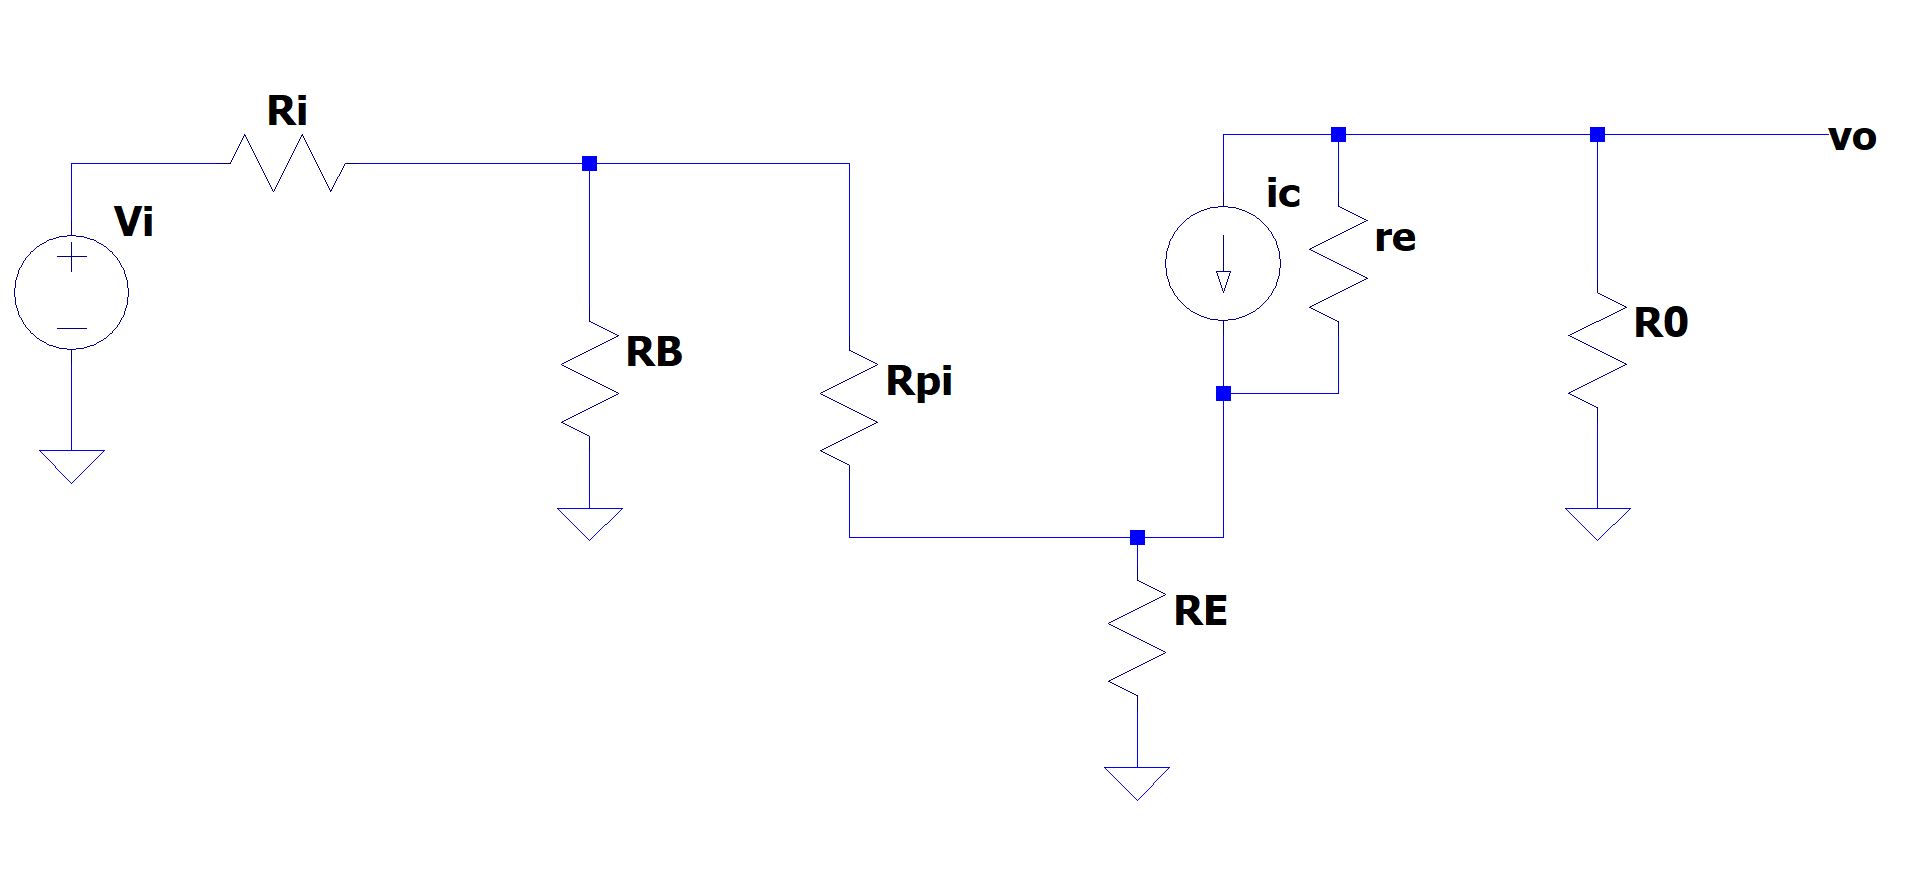

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

RiE1 = 100; %valor de entrada da figura 1
RCE1 = 18e+3;%valor de entrada da figura 1
RBE1 = RthE1; %calculado
R0E1 = RCE1%calculado R0

R0E1 = 18000

ReE1E1 = 180; %valor de entrada da figura 1  R2
VTE1 = 22e-3;%% Tensão termica dado no datasheet VT = (K*T)/q
viE1 = 35e-3

viE1 = 0.0350

### calculo do re e rpi:

reE1 = VTE1/IeE1

reE1 = 10.7198

rpiE1 = (BE1+1)*reE1

rpiE1 = 3.1195e+03

### **Calculo para CA**

ZbE1 = (BE1+1)*(ReE1E1+reE1)

ZbE1 = 5.5499e+04

vbE1 = (((1/RBE1)+(1/ZbE1))^-1/(RiE1+((1/RBE1)+(1/ZbE1))^-1))*viE1

vbE1 = 0.0333

ibE1 = vbE1/ZbE1

ibE1 = 6.0044e-07

icE1 = BE1*ibE1

icE1 = 1.7413e-04

ieE1 = (-vbE1+rpiE1*ibE1)/ReE1E1

ieE1 = -1.7473e-04

AvE1 = -BE1*((R0E1)/(RiE1+((RiE1/RBE1)+1)*(BE1+1)*(ReE1E1+reE1)))

AvE1 = -89.5517

voE1 = AvE1*viE1

voE1 = -3.1343

Z0E1 = R0E1

Z0E1 = 18000

veE1 = ReE1E1*ieE1

veE1 = -0.0315

vcE1 = voE1

vcE1 = -3.1343

ZiE1 = RiE1+((1/RBE1)+(1/rpiE1))^-1

ZiE1 = 1.3416e+03

Calculo dos Capacitores estagio 1:

fl = 20;
C1E1 = (1/2*pi)*(1/(0.1*fl*RiE1+((1/R1E1)+(1/R2E1)+(1/BE1*reE1))^-1))

C1E1 = 0.0069

C2E1 = (1/2*pi)*(1/(0.8*fl*(((1/REE1)+1/((reE1+((1/R1E1)+(1/R2E1)+(1/RiE1))^-1)))^-1)))

C2E1 = 0.0014

C3E1 = (1/2*pi)*(1/(0.1*fl*(RCE1)))

C3E1 = 4.3633e-05

## ESTAGIO 2

Figura 1- Circuito base

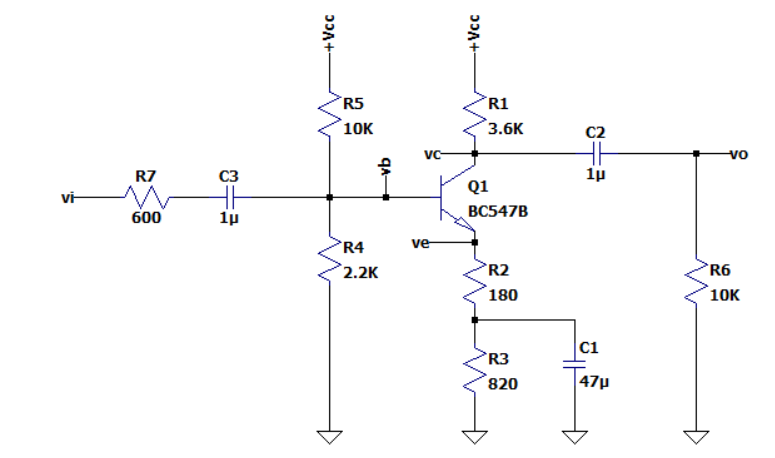

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

### Valores dos componentes:

R1E2 = 33e+3;%%Rth
R2E2 =2.2e+3;%%Rth
ReE1E2 = 10;
R3E2 = 190;
REE2 = ReE1E2+R3E2;%% R2+R3
VccE2 = 18;%%Variavel de entrada
BE2 = 290; % Beta para o calc
VbeE2 = 0.7; 
VceE2 = 5; %data sheet


### Equivalentes de TH

VthE2 = (R2E2/(R1E2+R2E2))*VccE2

VthE2 = 1.1250

RthE2 = ((1/R1E2)+(1/R2E2))^-1

RthE2 = 2.0625e+03

### Correntes

IbE2 = (VthE2-VbeE2)/(RthE2+REE2*(BE2+1))

IbE2 = 7.0525e-06

IcE2 = (BE2+1)*IbE2

IcE2 = 0.0021

IeE2 = IcE2

IeE2 = 0.0021

### Tensões CC

VbE2 = VthE2

VbE2 = 1.1250

VeE2 = REE2*IeE2

VeE2 = 0.4105

VcE2 = VceE2+VeE2

VcE2 = 5.4105

## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

RiE2 = 100; %valor de entrada da figura 1
RLE2 = 1.3e+3;%valor de entrada da figura 1
RCE2 = 300;%valor de entrada da figura 1
RBE2 = RthE2; %calculado
R0E2 = ((1/RLE2)+(1/RCE2))^-1%calculado R0

R0E2 = 243.7500

ReE1E2 = 180; %valor de entrada da figura 1  R2
VTE2 = 22e-3;%% Tensão termica dado no datasheet VT = (K*T)/q
viE2 = -voE1;

### calculo do re e rpi:

reE2 = VTE2/IeE2

reE2 = 10.7198

rpiE2 = (BE2+1)*reE2

rpiE2 = 3.1195e+03

### **Calculo para CA**

ZbE2 = (BE2+1)*(ReE1E2+reE2)

ZbE2 = 5.5499e+04

vbE2 = (((1/RBE2)+(1/ZbE2))^-1/(RiE2+((1/RBE2)+(1/ZbE2))^-1))*viE2

vbE2 = 2.9842

ibE2 = vbE2/ZbE2

ibE2 = 5.3771e-05

icE2 = BE2*ibE2

icE2 = 0.0156

ieE2 = (-vbE2+rpiE2*ibE2)/ReE1E2

ieE2 = -0.0156

AvE2 = -BE2*((R0E2)/(RiE2+((RiE2/RBE2)+1)*(BE2+1)*(ReE1E2+reE2)))

AvE2 = -1.2127

voE2 = AvE2*viE2

voE2 = -3.8009

Z0E2 = R0E2

Z0E2 = 243.7500

veE2 = ReE1E2*ieE2

veE2 = -2.8165

vcE2 = voE2

vcE2 = -3.8009

ZiE2 = RiE2+((1/RBE2)+(1/rpiE2))^-1

ZiE2 = 1.3416e+03

Calculo dos Capacitores estagio 1:

fl = 20;
C1E2 = (1/2*pi)*(1/(0.1*fl*RiE2+((1/R1E2)+(1/R2E2)+(1/BE2*reE2))^-1))

C1E2 = 0.0069

C2E2 = (1/2*pi)*(1/(0.8*fl*(((1/REE2)+1/((reE2+((1/R1E2)+(1/R2E2)+(1/RiE2))^-1)))^-1)))

C2E2 = 0.0014

C3E2 = (1/2*pi)*(1/(0.1*fl*(RCE2+RLE2)))

C3E2 = 4.9087e-04

Ganho:

AvT = AvE1*AvE2

AvT = 108.5975